**Lab 6**

**Setup**

*For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. *

Seems pretty straight-forward.

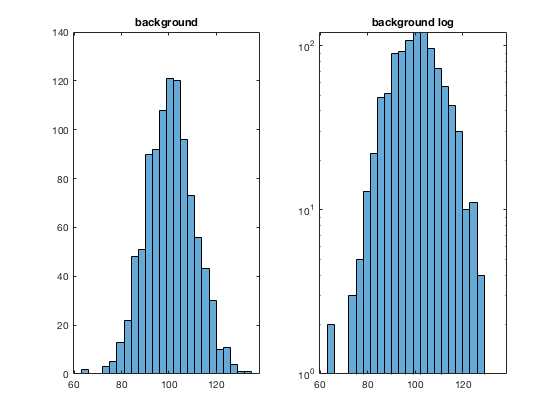

background = makedist('Poisson',"lambda",100);
bgP = random(background,[1 1000]);
figure;
subplot(1,2,1);
histogram(bgP);
title('background');
subplot(1,2,2);
histogram(bgP);
set(gca,'YScale',"log");
title('background log');

**Problem 1**

*Look at your background distribution and determine where the 5sigma threshold is.*

Once again, pretty straight-forward directions (first time?).

prob5sigma = 1/(3.5e6);%5 sigma ~ 1 in 3.5 million
thresh5sigma = icdf(background,1-prob5sigma)

thresh5sigma = 154

Looking at the background and the log background plots, a value of 154 makes sense as a threshold for 5-sigma detection.

**Problem 2**

*Now create a set of injected (simulated) signals of a single strength. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.*

*a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.*

I want to create a single data point and inject it into the background data.

First, I want to create a vector of signal points to be injected into the background.

shift = 230;%something large, ~ in the sigma range given
obsSign = zeros([1 1000]);
z = randi(10);
for i = 1:1000
    u = randi(10);
    if u == z
        obsSign(i) = shift;
    end
end

This should be a vector of the same size as the pdf of our background with most points as 0, but some points replaced by our signal (230). I want to then combine this vector with the background pdf vector.

signal = obsSign + bgP;

Plot the result.

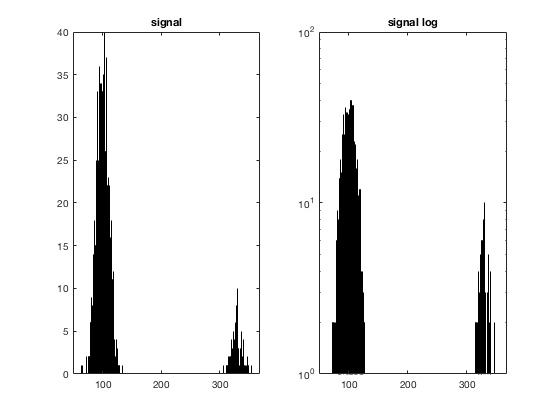

figure;
subplot(1,2,1);
histogram(signal,1000);
title('signal');
subplot(1,2,2);
histogram(signal,1000);
set(gca,'YScale',"log");
title('signal log');

The signal looks like the same original Poisson distribution centered at 100, except some of the points got moved and thus trace out another Poisson distribution near 330 (100 + 230). It is not complete because I did not inject that many points, but the shape resemblance is there. These look Gaussian because our Poisson has a large mean, and Poisson after many convolutions approaches a Gaussian.

This histogram is telling me that some signal should be present as there are two separate distributions created (should not be described by just our background distribution).

*b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?*

It is biased. It is not symmetric, in that it is likely to be weaker than the true injected signal, as can be seen from the distribution near 100 being larger than the distribution near 330. Interestingly, due to how we created this signal, we are very unlikely to get the true injected signal value by itself (230).

**Problem 3**

*Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). *

*a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal*

First, I want to create a background grid.

clear bgP signal;
bgP = random(background,[1000 1000]);

Next, I want to create a bunch of signal strengths evenly spaced between 0 and 400 (large value of sigma), and combine the vector of simulated signals with the background. I want to shift every single point in my original distribution by the signal strength (essentially, I am only looking at the "right" distributions from part 2).

signalstrength = linspace(0,400,1000);
[~,signal] = meshgrid(signalstrength);
observation = bgP + signal;

Plot this as a 2d histogram.

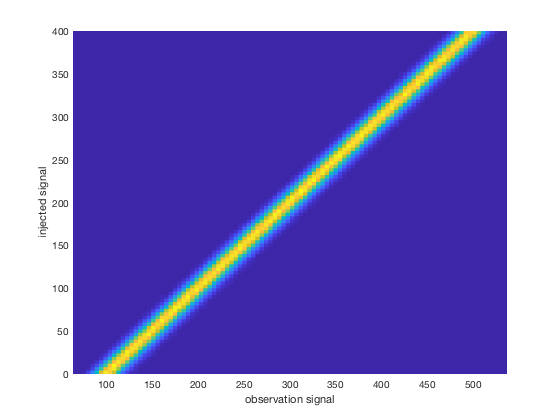

figure;
h = histogram2(observation,signal,100,"DisplayStyle",'tile','ShowEmptyBins','on');
xlabel('observation signal');
ylabel('injected signal');

*b) If you choose the same injected signal power as in problem 2, show that you get the same answer.*

We can see this from the graph, at an injected signal of 230, the values are centered at around 330, which is what we found in part 2.

We can check by looking at the 1d distribution of our observation matrix at the injected signal strength of 230.

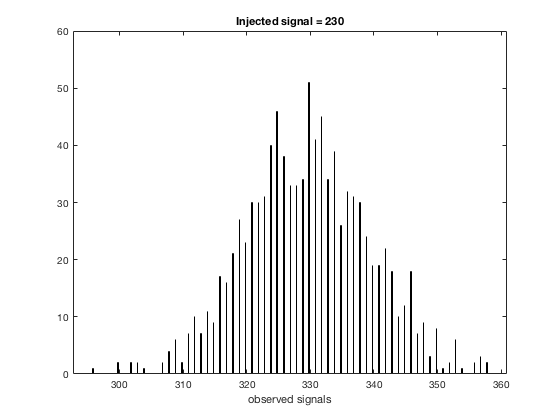

figure;
%there are 1000 points between 0 and 400, so 230 is 230/0.4 = 575
histogram(observation(575,:),1000);
xlabel('observed signals');
title('Injected signal = 230')

This looks like the distribution we had centered at 330 in part 2 (only the right part of it).

*c) Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.*

I am going to pick an observed signal of 440. The created histogram should give me the distribution of possible injected values that would result in an observed signal of 440.

First, I need to find the index of this observed signal. I can't simply pick out a column from my matrix as it is not necessarily evenly distributed.

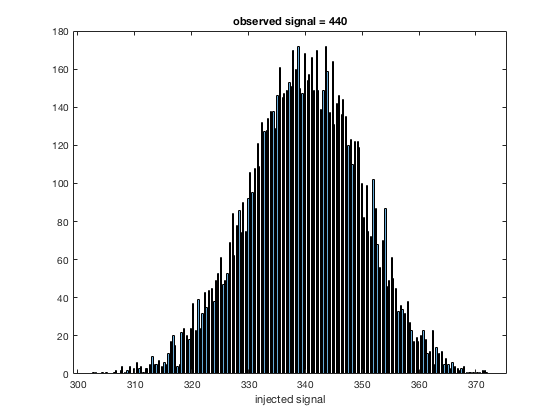

figure;
observ = 440;
inj = signal(abs(observation - observ)<2);
histogram(inj,300);
xlabel('injected signal');
title('observed signal = 440');

This histogram shows the probability of injected signal values that could result in an observed signal of 440 given the background distribution of our problem.

*d) For your observed signal, what is the 1σ uncertainty on the true signal strength?*

The "true signal strength" would be 340 in this case, as there is always a 100 signal shift due to the background and our signal being a shift from 100.

If I want to find the uncertainty, I should first normalize the distribution.

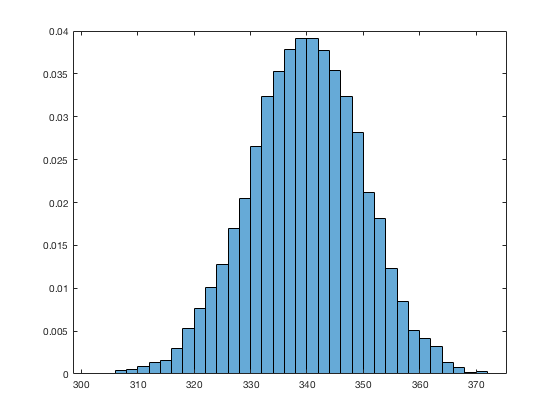

figure;
pdfInj = histogram(inj,'Normalization',"pdf");

This is an estimate for the probability density function of the data plotted in part d. 

Alternatively, I found a great function that returns points that correspond to percentiles of data. Therefore I want to look at percentiles corresponding to the bounds of 1 sigma. 1 sigma corresponds to containing 68% of the data, so if my data is a Gaussian (which is expected), then there will be 32% of the data contained outside of the bounds, meaning that my lower bound will be approximately the 16th percentile, and my upper bound will be approximately the 84th percentile.

zoop = prctile(inj,[16 84])

zoop =   329.9299  349.5576


The lower number corresponds to the lower bound, and the higher number to the upper bound. These values make sense when checking with either histogram (normalized approximated pdf and data).

I want the values into actual +- bounds, however.

lowB = abs(340-zoop(1,1))

lowB = 10.0701

upB = abs(340-zoop(1,2))

upB = 9.5576

Values are named self explanatory, but lower bound is lowB ~10.07, upper bound is upB ~9.56.

*e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?*

I've somewhat forced the bounds to be symmetric, however they aren't EXACTLY symmetric. We can tell that there is a slight deviation from the true value (340) that is different between the two bounds (seen in the difference between lowB and upB). But overall, I think I would argue that it is symmetric and unbiased. This would make sense because we're shifting our Gaussian distribution to be centered about some new value (shift is happening due to the injected signal), so it would also make sense that there would be a Gaussian range of injected signals that would correspond to the selected observation (as the deviation is created by our Poisson [approximated by Gaussian] distribution).

**Problem 4**

*Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).*

*a) Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.*

Directions are pretty self-explanatory. We need to pick a weak signal as our observed signal now. I will pick 113.

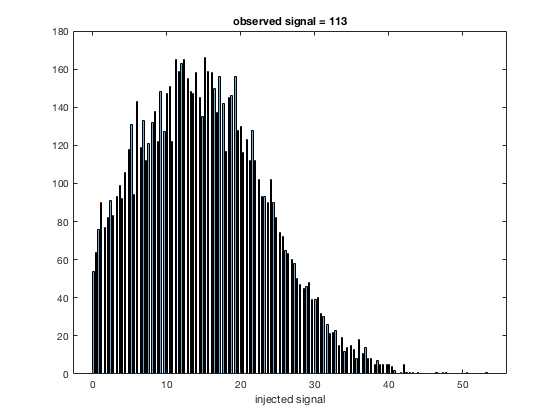

clear inj zoop lowB upB pdfInj
figure;
observ = 113;
inj = signal(abs(observation - observ)<2);
histogram(inj,300);
xlabel('injected signal');
title('observed signal = 113');

We can see that the distribution gets cut off at 0, as is expected. This histogram shows the probability of injected signal values that could result in an observed signal of 113 given the background distribution of our problem.

*b) Describe what it means to have the true signal pdf() extend to zero.*

If the true signal pdf goes all the way down to zero, then it means that the observed signal could have been entirely created by the background distribution. This is quite likely for very low signals, but becomes more and more impossible as the signals increase in value.

*c) Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is:  if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than X 95% of the time.]*

The 95% confidence upper bound is identical to the point Y, where if I integrate my data up to Y, 95% of the data would be contained within the area under the integral. Hence, I can once again use the dandy prctile function and find the 95th percentile.

upB = prctile(inj,95)

upB = 29.6296

The 95% confidence upper bound that I found is 29.6296, so 95% of the time, if we observe a signal of 113, the "true value" would be lower than 29.6296.